clf
point_xy=xlsread("data/ditushuju.xls")

point_xy =            1       14418        8046
           2       11664        8010
           3        8118        7974
           4        9162        7992
           5        9630        7992
           6        7398        7956
           7        4716        7956
           8        6750        7956
           9        1602        7938
          10        3528        7902


road_path=xlsread("data/ditushuju.xls",2)

road_path =      1     2
     1    35
     2     5
     2    21
     3     6
     3     4
     3    13
     4     5
     4    15
     5    16


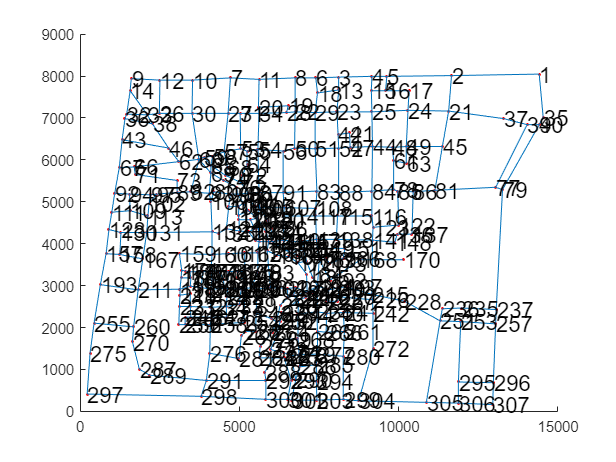


scatter(point_xy(:,2),point_xy(:,end),'.','r')
hold on
for i=1:length(road_path)
    point_id=road_path(i,:);
    point_start=point_id(1);
    point_end=point_id(2);
    point_start=point_xy(point_start,:,:);
    point_end=point_xy(point_end,:,:);
    x1=point_start(2);
    y1=point_start(3);
    x2=point_end(2);
    y2=point_end(3);
    distance=double(floor(vpa(norm([x1 y1]- [x2 y2]))));
    ans_b=(y1+y2)/2;
    ans_a=(x1+x2)/2;
%     text(ans_a,ans_b,{' ' distance},'fontsize',10);
%     text(ans_a,ans_b,{' ' distance},'fontsize',10);
%     text(ans_a,ans_b,' 1');Road Map with Distance
    line([x1 x2],[y1 y2]);
end
x=point_xy(:,[2]);
y=point_xy(:,[3]);
for i = 1:length(point_xy)  % 路口编号；    
    text(x(i)+10,y(i)+10,['',num2str(i),''],'fontsize',8);
end


point_xy=xlsread("data/ditushuju.xls")

point_xy =            1       14418        8046
           2       11664        8010
           3        8118        7974
           4        9162        7992
           5        9630        7992
           6        7398        7956
           7        4716        7956
           8        6750        7956
           9        1602        7938
          10        3528        7902


road_path=xlsread("data/ditushuju.xls",2)

road_path =      1     2
     1    35
     2     5
     2    21
     3     6
     3     4
     3    13
     4     5
     4    15
     5    16



clear
clc
a=0.95
k=[5;10;13;4;3;11;13;10;8;16;7;4];
k=-k;
d=[2;5;18;3;2;5;10;4;11;7;14;6];
restriction=46;
num=12;
sol_new=ones(1,num);
E_current=inf;
E_best=inf;
sol_current=sol_new;
sol_best=sol_new;
t0=97;
tf=3;
t=t0;
p=1;
while t>=tf
    for r=1:100
        %产生随机扰动
        tmp=ceil(rand.*num);
        sol_new(1,tmp)=~sol_new(1,tmp);
        %检查是否满足约束
        while 1
            q=(sol_new*d<=restriction);
            if ~q
                p=~p;
                tmp=find(sol_new==1);
                if p
                    sol_new(1,tmp)=0;
                else
                    sol_new(1,tmp(end))=0;
                end
            else
                break
            end
        end
        %计算背包中的物品价值
        E_new=sol_new*k;
        if E_new<E_current
            E_current=E_new;
            sol_current=sol_new;
            if E_new<E_best
                %把冷却过程中最好的解保存下来
                E_best=E_new;
                sol_best=sol_new;
            end
            else
                if rand<exp(-(E_new-E_current)./t)
                    E_current=E_new;
                    sol_current=sol_new;
                else
                    sol_new=sol_current;
                end
            end
        end
        t=t.*a;
    end
    disp('最优解为:')
    sol_best
    disp('物品总价值等于:')
    val=-E_best;
    disp(val)
    disp('背包中物品重量是：')
    disp(sol_best * d)
       

n=10
for i=10:-2:0
    i
end

method1

matrix=randsrc(500,337,[0,1;0.2,0.8])

matrix =      1     1     0     1     1     1     1     1     1     1     1     1     0     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     1     0     1     1     1     0     0     0     1     1     1     1     0     1
     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     1     1     0     1     1     1     1     1     1     1     0     1     1     1     0     1     1     1     0     1
     1     1     0     0     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0
     1     1     0     1     1     1     1     1     1     1     1     1     1     1    

num_1=sum(sum(matrix))

num_1 = 134874

method2

matrix=randsample([0 1],500*337,true,[0.2 0.8]);
matrix=reshape(matrix,500,337)

matrix =      1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     0     1     0     0     1     1     1     1     1     0     1     1     1     0     1     1     1     1     0     1     1     1     1     0     1     1     0     1     1     1     1     1     0     1     1
     1     1     0     1     1     1     0     1     0     1     1     1     1     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1
     1     0     1     1     1     1     0     1     0     1     0     1     1     1     1     1     1     1     1     1     1     0     1     1     0     1     0     1     1     1     0     1     0     1     1     0     1     1     1     1     1     0     0     1     0     1     1     1     1     1
     0     1     1     1     1     0     1     1     1     0     1     0     1     0    

num_1=sum(matrix(:)==1)

num_1 = 134925

method1: point

t=[0:0.5:20];
x=3.*t*sin(pi/3).*cos(2*t);
y=3.*t*sin(pi/3).*sin(2*t);
z=3.*t*cos(pi/3);
fi
plot3(x,y,z,'.-');

method2:function

u=0:0.01:11*pi;
x=2*sin(u);  
y=2*cos(u);
z=2*u;
plot3(x,y,z);

ezmesh('sin(x)+cos(y)')
ezsurf('sin(x)+cos(y)')




u=0:0.01:11*pi;
x=sin(u);  
y=cos(u);
z=x+y;
xlabel('x');
ylabel('y');
zlabel('z');
title('sin(x)+cos(y)')
plot3(x,y,z);




matrix=randi([-20+3 20+3],10,6)

matrix =     16   -11     9    11     0    -6
    20    22   -16   -16    -2    10
   -12    22    17    -6    14     9
    20     2    21   -16    15   -11
     8    15    10   -14   -10   -13
   -14   -12    14    16     3     3
    -6     0    13    11     1    22
     5    20    -1    -4     9    -4
    22    15     9    21    12     6
    22    22   -10   -16    13    -8


min_value=min(min(matrix))

min_value = -16